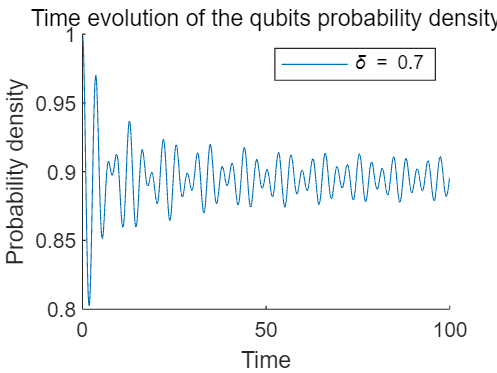

% Clear workspace, command window, and close all figures
clear;
clc;
close all;

% Coupling strength to be tested
delta = 0.7;
N = 50;
% Plot the time evolution of the qubit's probability density
figure;
hold on;
[time, prob_density_qubit, prob_density_full] = dynamics(delta);
plot(time, prob_density_qubit);
title('Time evolution of the qubits probability density');
xlabel('Time');
ylabel('Probability density');
legend(['\delta = ', num2str(delta)]);
hold off;

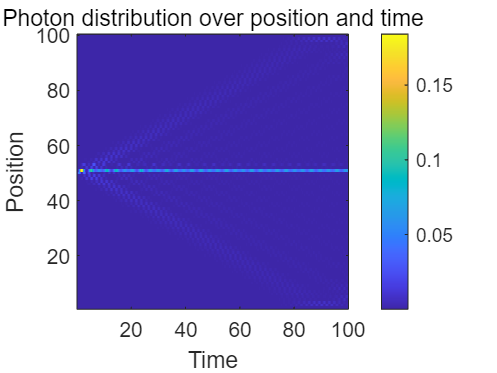


% Plot the photon distribution over position and time
figure;
imagesc(time, 1:2*N, prob_density_full(1:2*N, :)); % Exclude the qubit state
colorbar;
title('Photon distribution over position and time');
xlabel('Time');
ylabel('Position');
set(gca, 'YDir', 'normal'); % To set the y-axis in the correct direction

function [time, prob_density_qubit, prob_density_full] = dynamics(delta)
    % Set the length of the SSH chain (2N)
    N = 50;
    t1 = 1 - delta;  % Intracell coupling
    t2 = 1 + delta;  % Intercell coupling
    gamma = 0.4;  % Coupling strength between the qubit and the SSH chain
    
    % Create the Hamiltonian matrix
    H = zeros(2*N + 1);  % Include additional state for the qubit
    for i = 1:2*N-1
        if mod(i,2) == 1
            H(i,i+1) = t1;
            H(i+1,i) = t1;
        else
            H(i,i+1) = t2;
            H(i+1,i) = t2;
        end
    end
    
    % Coupling the qubit to the left end of the SSH chain
    H(N, 2*N+1) = gamma;
    H(2*N+1, N) = gamma;
    
    % Initialize the qubit in the excited state
    psi0 = zeros(2*N + 1, 1);
    psi0(end) = 1;  % The qubit is at the last position (excited state)
    
    % Time evolution parameters
    t_max = 100;  % Maximum time
    dt = 0.05;  % Time step
    time_steps = t_max / dt;
    time = (1:time_steps) * dt;
    psi_t = psi0;
    prob_density_full = zeros(2*N+1, time_steps);
    
    % Time evolution
    for t = 1:time_steps
        psi_t = expm(-1i * H * dt) * psi_t;  % Time evolution operator
        prob_density_full(:, t) = abs(psi_t).^2;  % Probability density at each site
    end
    
    % Extract the probability density of the qubit
    prob_density_qubit = prob_density_full(end, :);
end
